# Adaptive Noise Canceller

Akwasi D. Akwaboah

05/13/2021

Project Description: Data Acquisition from the arduino and analysis

## 1. Hardware Implementation

### 1.1. Serial Data Collection from Arduino

%Author: Akwasi D. Akwaboah
%Date: 05/11/2021
%Project Description: Data Acquisition from the arduino and analysis

clear all
serialportlist("available")';
arduinoObj = serialport("COM6",9600);
configureTerminator(arduinoObj,"LF");
flush(arduinoObj);
arduinoObj.UserData = struct("Data",[zeros(4, 2000)],"Count",1); %specify sample size here
write(arduinoObj,1,"uint8");
configureCallback(arduinoObj,"terminator",@readData);


### 1.2. Visualizations

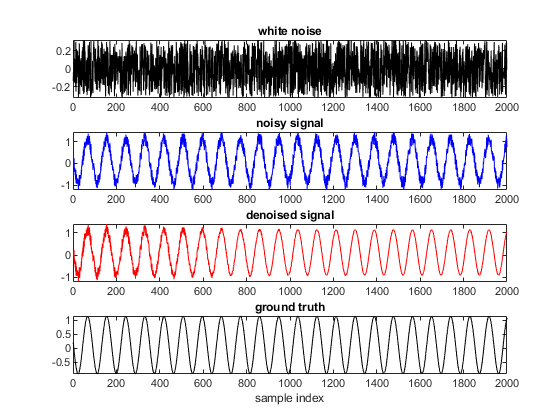

%Please wait a while for data collection to complete
%Otherwise you will see all zeros.
%Run when arduino blinking LED stops.
%Press arduin reset button on rerun to initialize weights and filter values
%for reproducibility
figure
subplot(4, 1, 1)
plot(arduinoObj.UserData.Data(1, 1:end), '-k'); %noise
title('white noise')
subplot(4, 1, 2)
plot(arduinoObj.UserData.Data(3, 1:end), '-b'); %noisy signal
title('noisy signal')
subplot(4, 1, 3)
plot(arduinoObj.UserData.Data(4, 1:end), '-r'); %denoised signal
title('denoised signal')
subplot(4, 1, 4)
plot(arduinoObj.UserData.Data(2, 1:end), '-k'); %ground truth
title('ground truth')
xlabel('sample index')

### 1.3. Analysis

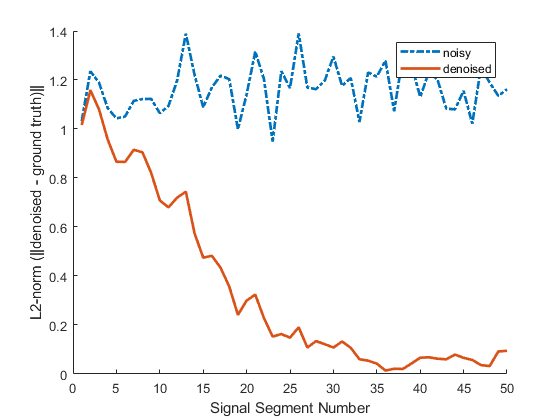

ard_data = arduinoObj.UserData.Data;
n_pts = 50; % number of segments
data_len = length(ard_data(3, :));
noisy_snr_arr = zeros(1, n_pts);
denoised_snr_arr = zeros(1, n_pts);


for i = 1:n_pts
    noisy_snr_arr(i) = vecnorm(ard_data(3, (i-1)*data_len/n_pts + 1: i*data_len/n_pts)- ...
        ard_data(2, (i-1)*data_len/n_pts + 1: i*data_len/n_pts));
    denoised_snr_arr(i) = vecnorm(ard_data(4, (i-1)*data_len/n_pts + 1: i*data_len/n_pts)- ...
        ard_data(2, (i-1)*data_len/n_pts + 1: i*data_len/n_pts));
end
figure
hold on
plot(noisy_snr_arr, '-.', "LineWidth", 2)
plot(denoised_snr_arr, '-', "LineWidth", 2)
legend('noisy', 'denoised')
hold off
xlabel('Signal Segment Number')
ylabel('L2-norm (||denoised - ground truth)||')

## 2. Simulations (Experiments)

### 2.1. Exploring Learning rate ($\mu$)

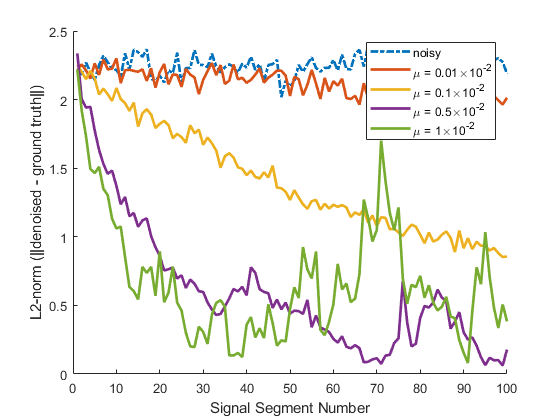

close all
clear all
n_pts = 100;

noisy_snr_arr = zeros(1, n_pts);
denoised_snr_arr = zeros(5, n_pts);
A = load('ANC_data.mat'); % Exported Python Simulation Data
C = struct2cell(A);
noise = C{5, 1};
noisy_sig = C{6, 1};
desired_sig = C{7,1};
data_len = length(noisy_sig);
for i = 1:n_pts
    noisy_snr_arr(i) = vecnorm(noisy_sig((i-1)*data_len/n_pts + 1: i*data_len/n_pts) - ...
        desired_sig((i-1)*data_len/n_pts + 1: i*data_len/n_pts));
end

for j = 1:5
    sim_data = C{j,1};
    for i = 1: n_pts
        denoised_snr_arr(j,i) = vecnorm(sim_data((i-1)*data_len/n_pts + 1: i*data_len/n_pts) - ...
            desired_sig((i-1)*data_len/n_pts + 1: i*data_len/n_pts));
    end
end
figure
hold on
plot(noisy_snr_arr, '-.', "LineWidth", 2)
for j = 1:4
    plot(denoised_snr_arr(j,:), '-', "LineWidth", 2)
end
legend('noisy', '\mu = 0.01\times10^{-2}', '\mu = 0.1\times10^{-2}',  '\mu = 0.5\times10^{-2}', ...
    '\mu = 1\times10^{-2}', "Location","northeast")
hold off
xlabel('Signal Segment Number')
ylabel('L2-norm (||denoised - ground truth||)')

### 2.2. Exploring Weiner Filter Size ($N$)

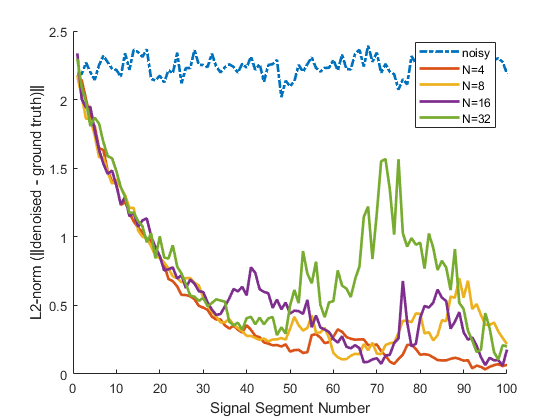

close all
clear all
n_pts = 100;

noisy_snr_arr = zeros(1, n_pts);
denoised_snr_arr = zeros(5, n_pts);
A = load('ANC_data_N.mat'); % Exported Python simulation Data
C = struct2cell(A);
noise = C{5, 1};
noisy_sig = C{6, 1};
desired_sig = C{7,1};
data_len = length(noisy_sig);
for i = 1:n_pts
    noisy_snr_arr(i) = vecnorm(noisy_sig((i-1)*data_len/n_pts + 1: i*data_len/n_pts) - ...
        desired_sig((i-1)*data_len/n_pts + 1: i*data_len/n_pts));
end

for j = 1:5
    sim_data = C{j,1};
    for i = 1: n_pts
        denoised_snr_arr(j,i) = vecnorm(sim_data((i-1)*data_len/n_pts + 1: i*data_len/n_pts) - ...
            desired_sig((i-1)*data_len/n_pts + 1: i*data_len/n_pts));
    end
end
figure
hold on
plot(noisy_snr_arr, '-.', "LineWidth", 2)
for j = 1:4
    plot(denoised_snr_arr(j,:), '-', "LineWidth", 2)
end
legend('noisy', 'N=4', 'N=8',  'N=16', 'N=32', "Location","northeast")
hold off
xlabel('Signal Segment Number')
ylabel('L2-norm (||denoised - ground truth)||')

function readData(src, ~) % reference: https://www.mathworks.com/help/matlab/ref/serialport.configurecallback.html
% Read the ASCII data from the serialport object.
data = readline(src);

% Convert the string data to numeric type and save it in the UserData
% property of the serialport object.
src.UserData.Data(mod(src.UserData.Count,4)+1, ceil(src.UserData.Count/4)) = str2double(data);

% Update the Count value of the serialport object.
src.UserData.Count = src.UserData.Count + 1;

% If 1001 data points have been collected from the Arduino, switch off the
% callbacks and plot the data.
if src.UserData.Count >= 8000 % (4 x 2000)
    write(src,0,"uint8") %end stream data stream - blinking LED on arduino should turn off
    configureCallback(src, "off");
end
end
